1.1  （黄金分割比）实时脚本

由张志涌编写、修改于 2023.1。

1）

disp('1)+++++++++++++++++++++++++++++')

1)+++++++++++++++++++++++++++++


phi = (1 + sqrt(5))/2

phi = 1.6180

format long 
phi

phi =    1.618033988749895


2）

disp('2)+++++++++++++++++++++++++++++')

2)+++++++++++++++++++++++++++++


p = [1 -1 -1];
r = roots(p)

r =   -0.618033988749895
   1.618033988749895


3）

disp('3)+++++++++++++++++++++++++++++')

3)+++++++++++++++++++++++++++++


syms x
r = solve(1/x == x-1)

$$r = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{5}}{2}\\ \frac{\sqrt{5}}{2}+\frac{1}{2} \end{array}\right)$$

pretty(r)

/ 1   sqrt(5) \
| - - ------- |
| 2      2    |
|             |
| sqrt(5)   1 |
| ------- + - |
\    2      2 /



phi = r(2)

$$phi = \frac{\sqrt{5}}{2}+\frac{1}{2}$$

vpa(phi,50)

$$ans = 1.6180339887498948482045868343656381177203091798058$$

phi = double (phi)

phi =    1.618033988749895


4）

disp('4)+++++++++++++++++++++++++++++')

4)+++++++++++++++++++++++++++++


f=@(x)1./x-(x-1)

f = 包含以下值的 function_handle :
    @(x)1./x-(x-1)


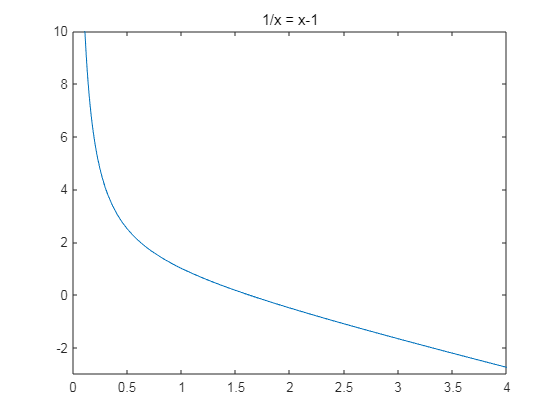

fplot(f,[0,4])
ylim([-3,10])
title('1/x = x-1')

5）

disp('5)+++++++++++++++++++++++++++++')

5)+++++++++++++++++++++++++++++


phi = fzero(f,1)

phi =    1.618033988749895


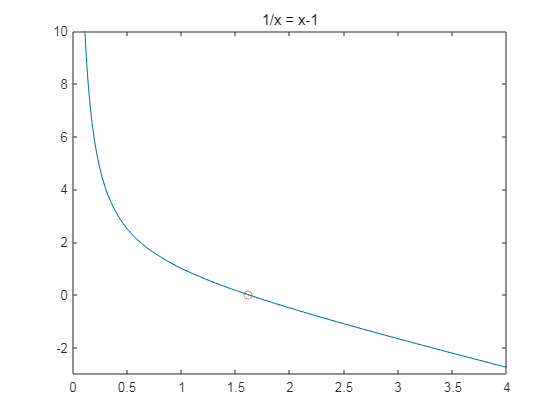

hold on
plot(phi,0,'o')
hold off

6）

disp('6)+++++++++++++++++++++++++++++')

6)+++++++++++++++++++++++++++++


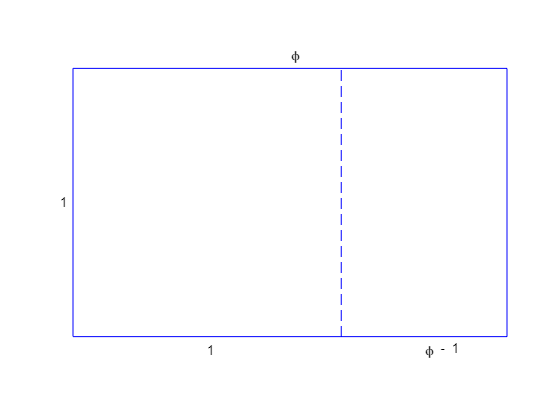

figure
goldrect

7）

disp('7)+++++++++++++++++++++++++++++')

7)+++++++++++++++++++++++++++++


goldfract(6)

p = '1+1/(1+1/(1+1/(1+1/(1+1/(1+1/(1))))))'

p = '21/13'

p =    1.615384615384615


err = 0.0026

function goldfract(n)
%GOLDFRACT   Golden ratio continued fraction.
%  GOLDFRACT(n) displays n terms.

%   Copyright 2012 Cleve Moler and The MathWorks, Inc.

p = '1';
for k = 1:n
   p = ['1+1/(' p ')'];
end
p

p = 1;
q = 1;
for k = 1:n
   s = p;
   p = p + q;
   q = s;
end
p = sprintf('%d/%d',p,q)

format long
p = eval(p)

format short
err = (1+sqrt(5))/2 - p
end